# ECE 6530: Final Project

*M. Adkins, F. Mino, F. Ordubadi, and V. Rao (2023)*

## Data Acquisition

This data is meant to simulate Peripheral Nervous System (PNS) neural data collected as described in Fig. 3.1-2 of [Warren et. al 2016](https://doi-org.ezproxy.lib.utah.edu/10.1109/JPROC.2015.2507180).

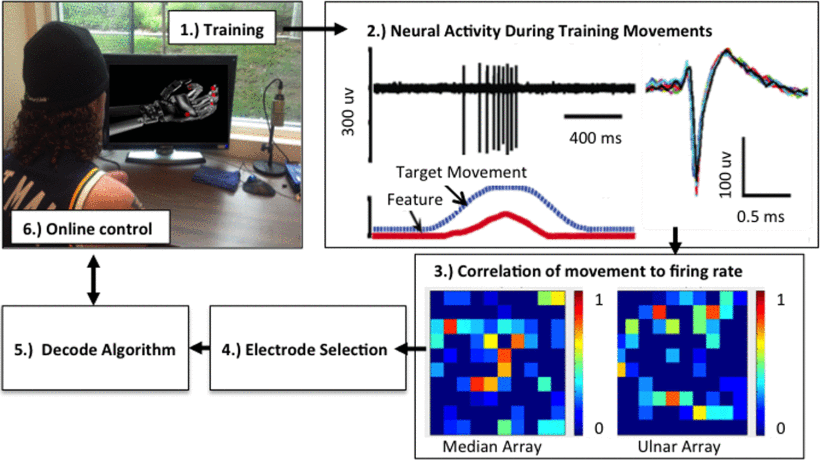

## Load Data

This is simulated data provided for the Introduction to NeuroRobotics course by Jacob George, PhD.

load("./data/project_data.mat")

## Visualize Data

### Neural Data

fs = 30e3; % sampling frequency
t = (1:length(unfilteredNeuralData))'/fs;
tlo = tiledlayout('flow');
ax = [];%
for channel = 1:6
    ax(channel) = nexttile; plot(t, unfilteredNeuralData(:,channel), 'k')
    ylabel("Voltage")
    xlabel("Time [sec]")
    title(sprintf("Channel %d", channel))
    box off
end
linkaxes(ax, 'y')

### Target Movements (a.k.a. Kinematics)

tlo = tiledlayout(3,1);
for finger=1:2
    nexttile; plot(t, Kinematics(:,finger))
    ylabel("Joint Angle")
    xlabel("Time [sec]")
    title(sprintf("Finger %d", finger))
    box off
end
nexttile; plot(t, Kinematics)
ylabel("Joint Angle")
xlabel("Time [sec]")
title("Fingers 1 and 2")
box off

### Combined Visualization

tlo = tiledlayout('flow');

my_palette = [24,24,24; 13,53,128; 210,41,45]/(255);
set(tlo,'DefaultAxesColorOrder', my_palette)
ax = [];

raw_data_norm = unfilteredNeuralData/max(unfilteredNeuralData(:));
for channel = 1:6
    ax(channel) = nexttile;
    plot(t, raw_data_norm(:,channel));
    hold on
    plot(t, Kinematics, LineWidth=2.25)
    hold off
    box off
    title(sprintf("Channel %d", channel))
    xlabel("Time [sec]")
    if channel==1
        legend({"Raw Neural Data", "Finger 1", "Finger 2"}, Location = 'northoutside', Orientation='horizontal')
    end
end
linkaxes(ax, 'y')

## Project Description

It is known that neural data is **nonlinear, nonstationary, and noisy**. [[Wu et al. 2008](https://doi.org/10.1109%2FTNSRE.2008.922679)]

The NeuroRobotics Lab at the University of Utah has attempted to decode Kinematic data from Neural data by using time-domain features, notably, MAV and spike rates. [[Page et al. 2018](https://doi.org/10.3389/fnhum.2018.00352)]

In this project, we will explote time-frequency features for a regression algorithm such as a Kalman Filter or a Neural Network.

We have selected three methods based on Table 1. of [Huang et al. 2008](https://doi.org/10.1029/2007RG000228)

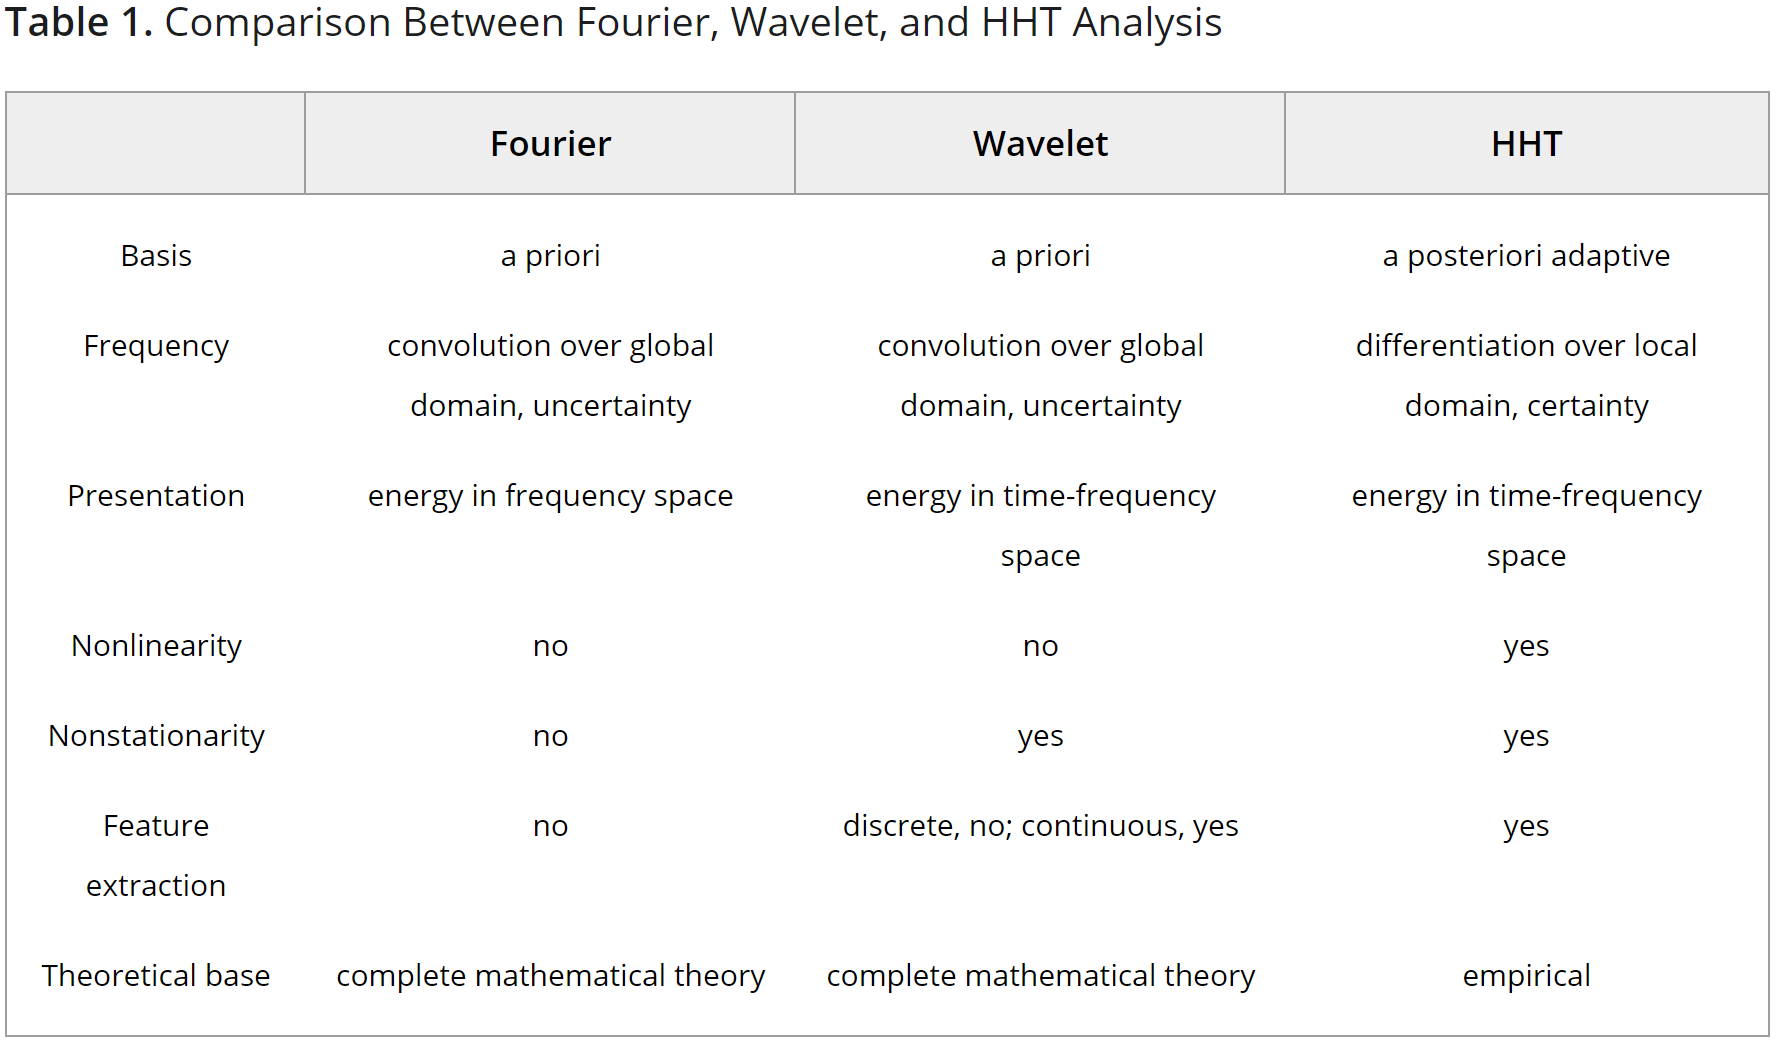

All three of these methods will output a time-frequency image (2D) signal for each channel. These new signals can then be fed to the regressors, and decoding performance should serve as a comparison metric for each of the methods.

#### STFT

[MATLAB STFT Tutorial](https://www.mathworks.com/help/signal/ref/stft.html)

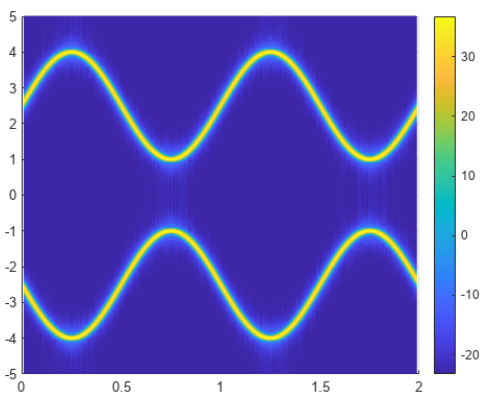

#### Wavelet Transform (Discrete & Continuous)

[MATLAB Wavelet Analysis of Frequency Bank Tutorial](https://www.mathworks.com/help/wavelet/ug/continuous-and-discrete-wavelet-analysis.html)

#### 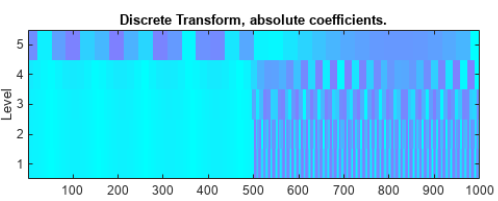

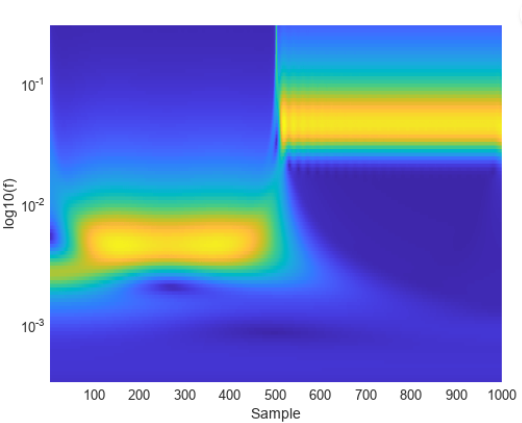

#### Hilbert-Huang Transform

[MATLAB HHT Tutorial](https://www.mathworks.com/help/signal/ref/hht.html)

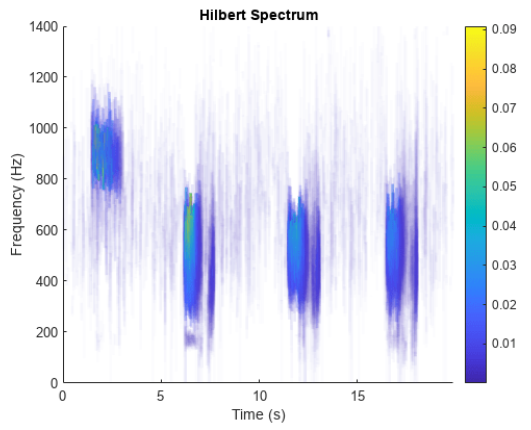

#### Example of Desired Ouput Plot

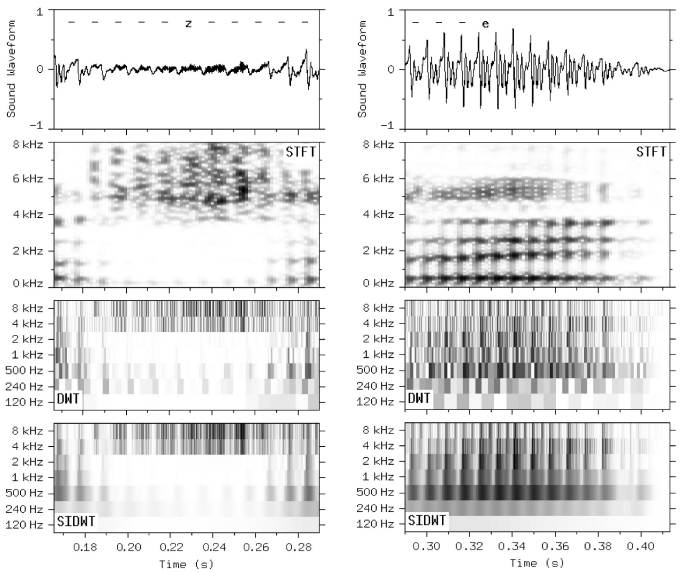

## STFT

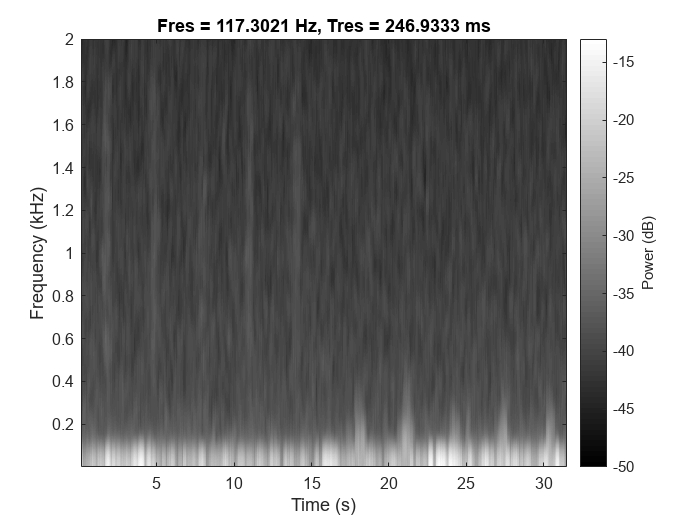

signal = raw_data_norm(:,1);
tlo = tiledlayout('flow');
pspectrum(signal,fs,'spectrogram','Leakage',0.2,'OverlapPercent',80,'FrequencyLimits',[1 2000],'MinThreshold',-50)

## DWT

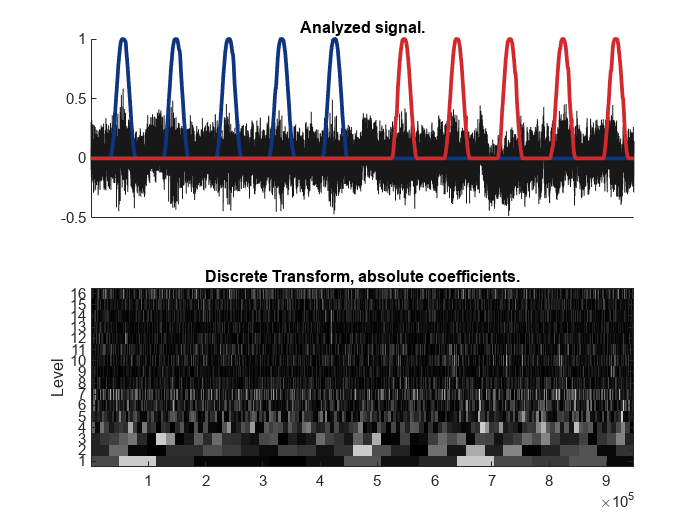

lev   = 16;
wname = 'fk4'; 
nbcol = 64; 
[c,l] = wavedec(signal,lev,wname);


len = length(signal);
cfd = zeros(lev,len);
for k = 1:lev
    d = detcoef(c,l,k);
    d = d(:)';
    d = d(ones(1,2^k),:);
    cfd(k,:) = wkeep(d(:)',len);
end
cfd =  cfd(:);
I = find(abs(cfd)<sqrt(eps));
cfd(I) = zeros(size(I));
cfd    = reshape(cfd,lev,len);
cfd = wcodemat(cfd,nbcol,'row');

figure
h211 = subplot(2,1,1);
h211.XTick = [];
set(gca,'ColorOrder', my_palette, 'NextPlot', 'replacechildren');
plot(signal); 
hold on
plot(Kinematics, LineWidth=2.25)
hold off
title('Analyzed signal.');
ax = gca;
ax.XLim = [1 length(signal)];
subplot(2,1,2);
colormap(gray(80));
image(flip(cfd));
tics = 1:lev; 
labs = int2str(tics');
ax = gca;
ax.YTickLabelMode = 'manual';
ax.YDir = 'normal';
ax.Box = 'On';
ax.YTick = tics;
ax.YTickLabel = labs;
title('Discrete Transform, absolute coefficients.');
ylabel('Level');

## CWT

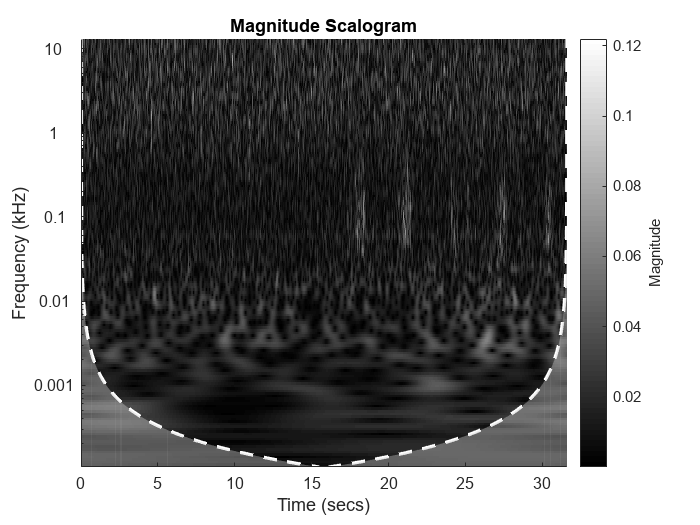

cwt(signal, fs)

## HHT

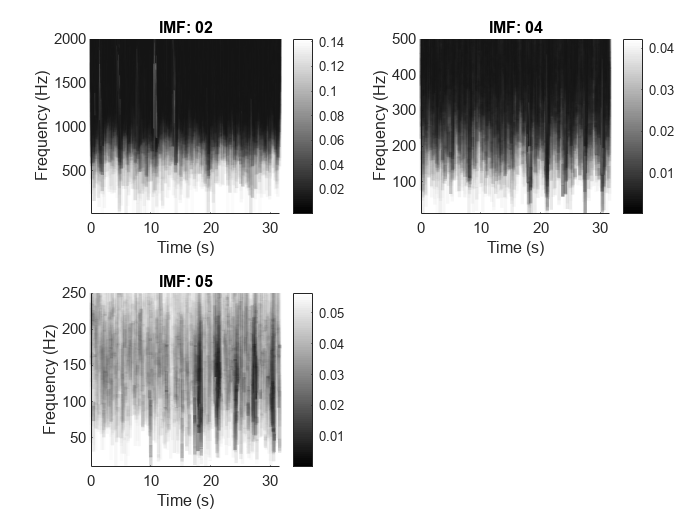

n_imf = 7;
imf = emd(signal,'MaxNumIMF',n_imf,'Display',0);

tlo = tiledlayout('flow');
ax = [];
for i = [2,4,5]
ax(i) = nexttile;
hht(imf(:,i),fs,FrequencyLimits=[10 8000/(2^i)])
title(sprintf("IMF: %02d", i))
end
colormap(ax(2), gray(80));
colormap(ax(4), gray(80));
colormap(ax(5), gray(80));